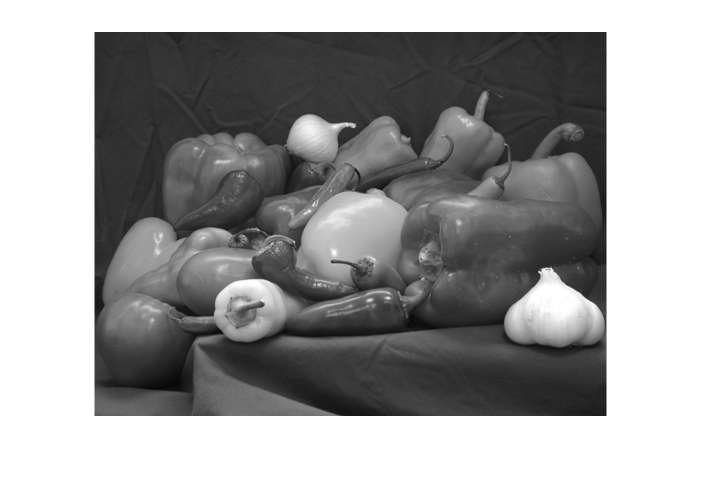

clear; clc; close all;

A = imread('peppers.png');
B = rgb2gray(A);
imshow(B)

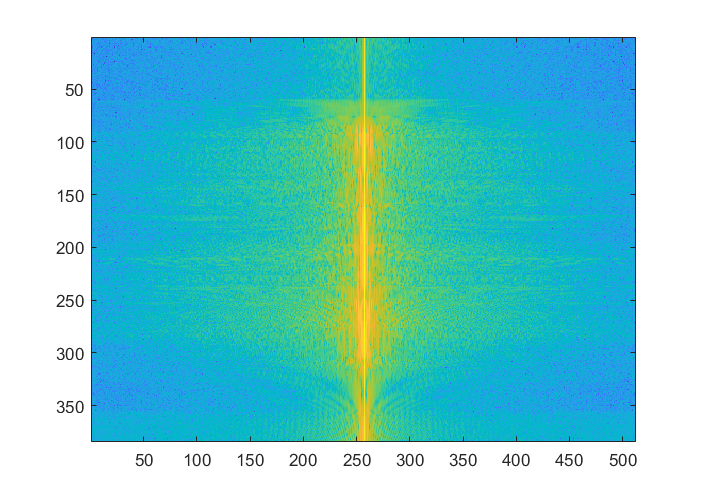

for j = 1:size(B,1)
    Cshift(j,:) = fftshift(fft(B(j,:)));
    C(j,:) = fft(B(j,:));
end

imagesc(log(abs(Cshift)))

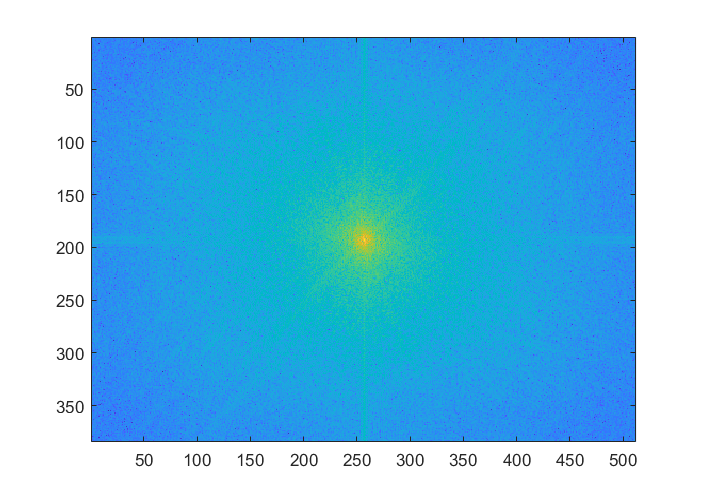

for j=1:size(C,2)
    % Compute column-wise FFT
    D(:,j) = fft(C(:,j));
end
imagesc(fftshift(log(abs(D))))

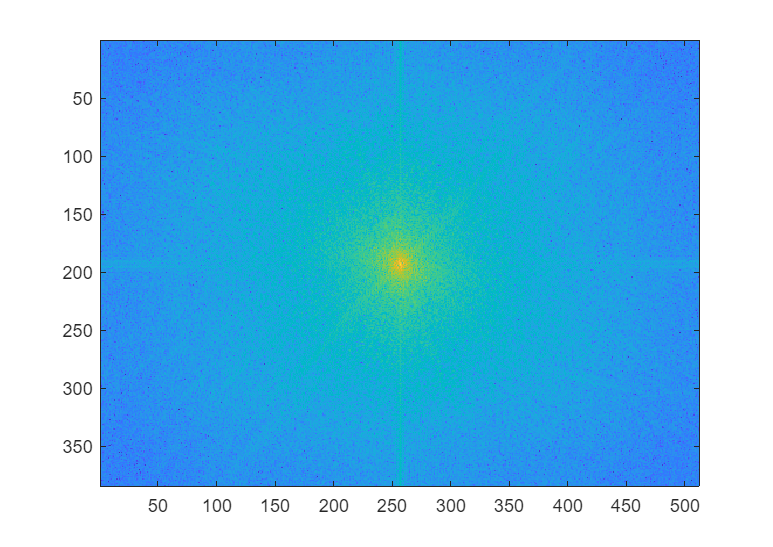

D = fft2(B); % Much more efficient to use fft2
imagesc(fftshift(log(abs(D))))

Image Compression and reconstruction using FFT2

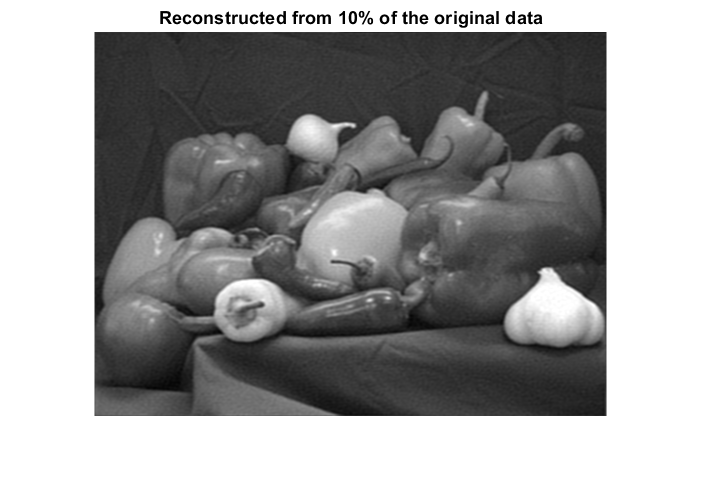

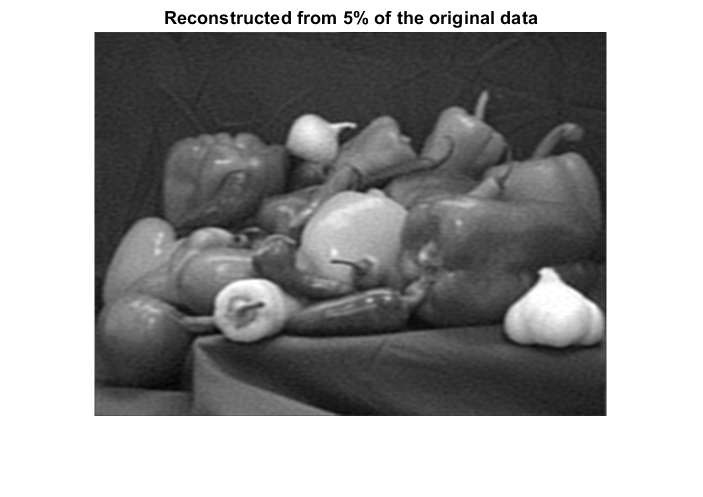

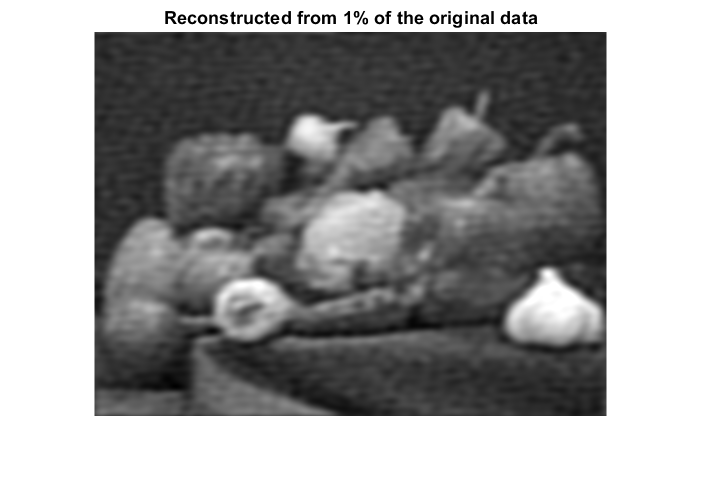

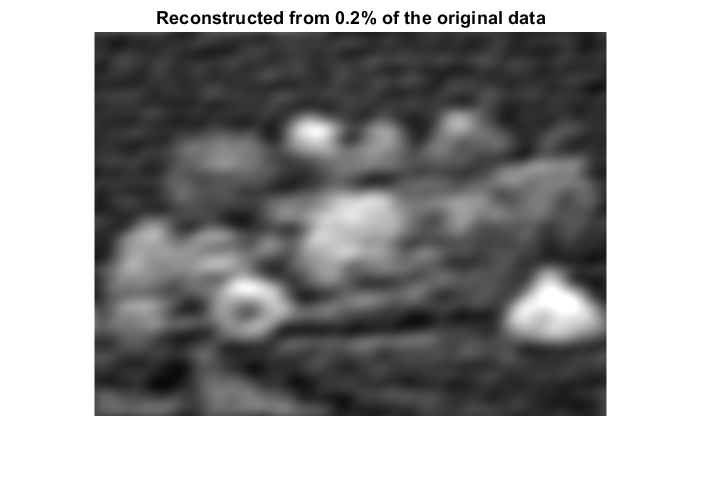

Bt = fft2(B); %2-D fft
Btsort = sort(abs(Bt(:))); %sort by magnitude

for keep = [.1 .05 .01 .002] %percentage of the fft2 matrix to keep   
    thresh = Btsort(floor((1-keep)*length(Btsort)));
    ind = abs(Bt) > thresh;
    Atlow = Bt.*ind;
    Alow = uint8(ifft2(Atlow));
    figure; 
    imshow(Alow)

    title("Reconstructed from " + keep*100 + "% of the original data")
end